# **垂直跳び　床反力分析**

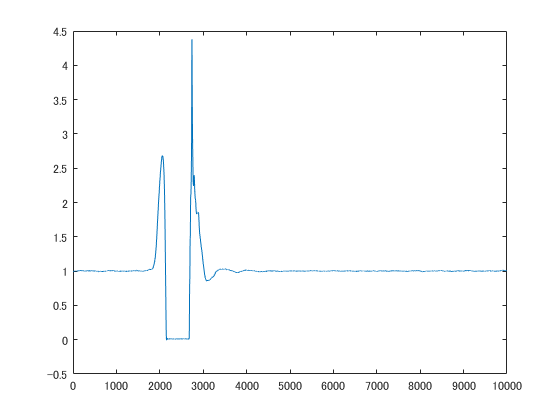

clear
close all
clc


% load 
fileName = 'DemoDataSJ' ;
load(fileName) ;

% 図を作成して、床反力波形を確認
fz = grfs(:,3) + grfs(:,6) ;
plot(fz)

# **イベント検出**

時系列データから、イベントを検出する。

今回の目標は、ジャンプ動作の開始・離地・着地

## １．波形をプロットし、何を検出したいのかを整理する

教科書や論文に載っている図や記述を参考にするとよい

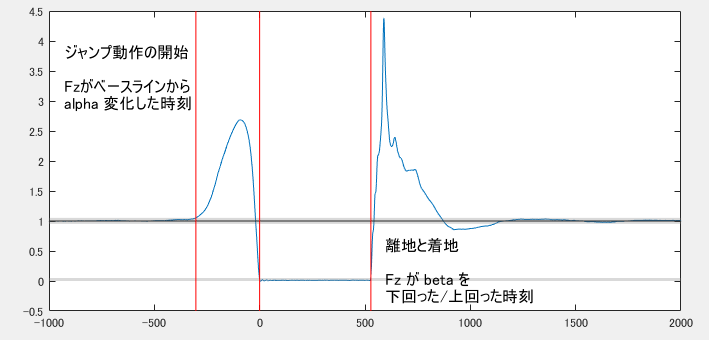

## イベント条件の定義

イベント検出のためには、イベント条件を、数式で定義する必要がある

※　プログラムは、fz(i) < beta を満たす最小の i は検出できるが、"離地の瞬間" は検出できない

※　コードインタプリターを用いればできるわけですが、プログラミング初心者は、いったん簡単な例でプログラムの挙動を理解した方が良いよいと思います。

ここでは、以下のように定義し、それに従い、コーディングしていきましょう

ジャンプ動作の開始：　Fz が、一定時間の間（winとする）、ベースラインから一定程度（alphaとする）乖離した時刻

離地と着地：　Fz が、一定時間の間（winとする）、一定の閾値（beta とする）を下回った/上回った時刻

※　alpha, beta は検出に用いたパラメータで、論文では、これらの値やアルゴリズムが書かれている

% 閾値パラメータ
% 閾値パラメータは、プログラム冒頭部などに、まとめて書いておいたが見やすいでしょう
alpha = 0.03 ; % ジャンプ動作開始　[per weight]
beta = 0.03 ; % 離地・着地 [per weight]
win = 50 ; % 時間条件 [ms] 　（一瞬だけ変化した、みたいな誤検出を防ぐことができる）

% イベント検出に共通しても用いる変数
n = length(fz) ;
baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                            %　なので、測定開始後1秒は静止していなければならない


## ジャンプ動作開始時刻


tOnsetJump = 1 ; % 変数の初期化

for ii = 2:n-win
    % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
    criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;

    % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
    criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;

    if criteria1 && criteria2 % 上記の2条件を同時に満たす
        tOnetJump = ii ;
        break % 1回検出したら、ループを抜ける
    end
    
end



## 離地と着地

% takeoff
for ii = 2:n-win
    if all( fz(ii:ii+win) < beta )
        tTakeOff = ii ;
        break
    end
end

% landing
for ii = tTakeOff:n-win
    if all( fz(ii:ii+win) > beta )
        tLanding = ii ;
        break
    end
end


[tOnsetSJ, baseFz] = detect_SJ_onset(fz, alpha)

tOnsetSJ = 1827

baseFz = 1.0022

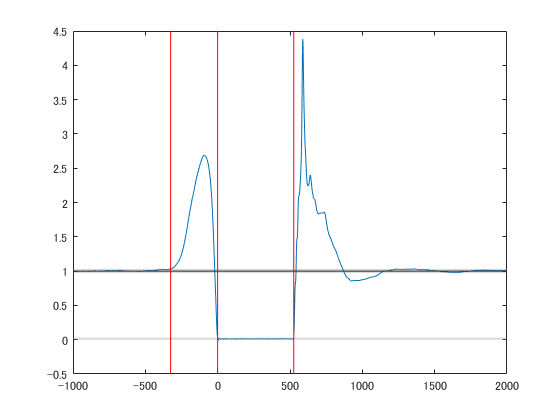



% % takeoff
% beta = 0.05 ;
% win = 30 ;
% n = length(fz) ;
% for ii = tOnsetSJ:n-win
%     if all( fz(ii:ii+win) < beta )
%         tTakeOff = ii ;
%         break
%     end
% end
% 
% % landing
% for ii = tTakeOff:n-win
%     if all( fz(ii:ii+win) > beta )
%         tLanding = ii ;
%         break
%     end
% end


% power
y2dot = (fz - 1) * gravity ;  % [m/s2]
ydot = cumtrapz(y2dot) * 0.001 ; % [m/s]
y = cumtrapz(ydot) * 0.001 ; % [m]
y = y - y(tOnsetSJ) ;

grfPower = fz.*ydot ; % [N/weight * m/s] = [J/s /weight] = [W/weight]
peakPower = max(grfPower) * gravity ; % [W / kg] ### weight = m [kg] * g [m/s2]

%
tData = [1:n] - tTakeOff ;

figure
plot(tData, fz)
lineplot(1, 'h', 'k') ;
arealine([baseFz-alpha, baseFz+alpha], 'h') ;
arealine([0, beta], 'h') ;
lineplot(tData([tOnsetSJ, tTakeOff, tLanding]), 'v', 'r') ;



set(gca, 'xlim', [-1000,2000])

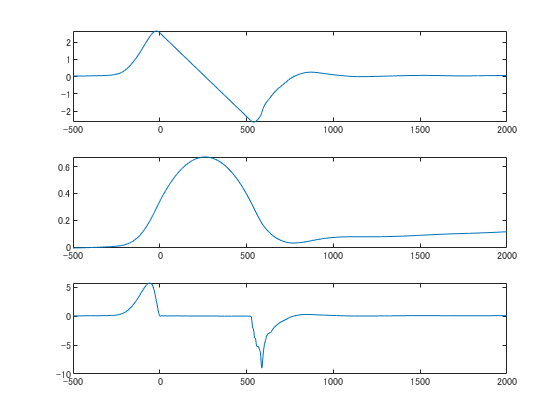


figure
subplot(3,1,1) ;
plot(tData, ydot)
set(gca, 'xlim', [-500,2000])

subplot(3,1,2) ;
plot(tData, y)
set(gca, 'xlim', [-500,2000])

subplot(3,1,3) ;
plot(tData, grfPower)
set(gca, 'xlim', [-500,2000])

function D = load_sample_data()

    clear
    close all
    clc
    
    iSubject = 99 ;
    dataFilePath = sprintf('../data matfiles 1/Data_S%02d', iSubject) ;
    load(dataFilePath) ;
    
    D = DataStruct.SJ(1) ;

end


function [onset, baseFz] = detect_SJ_onset(fz, alpha)

    baseWindow = 1000 ;
    baseFz = mean(fz(1:baseWindow)) ;
    
    win = 30 ;
    n = length(fz) ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) > baseFz+alpha ) || all( fz(ii:ii+win) < baseFz-alpha ) 
            onset = ii ;
            break
        end
    end
    
end

